# Example: Basic Solver for Acoustics in 1D with PML

This live-script features the following:

- how to set up PML in 1D

Refer to `ex_Acoustic1D_basic.mlx `for more explanation on the basic set up.

clear

domain_x = [0,1];
domain_t = [0,1.2];

% Computational grids and grid spaces
Nx     = 401; %number of spatial grid points
gsp_P  = GridSpace1D(Grid1DUnifPrimal(domain_x,Nx)); %grid space for pressure
dx     = gsp_P.h; %spatial grid size

% Acoustic medium
medium = AcousticMedium1D.constant(KappaValue=1,BetaValue=1);
[~,~,~,cMax] = sampleMedium1D(gsp_P,medium);

% Time grid (computed after medium)
CFL_factor = 0.9;
dt = CFL_factor*(6/7)*dx/cMax; %CFL condition for 2-4 FDM
Nt = ceil(diff(domain_t)/dt)+1;
dt = diff(domain_t)/(Nt-1); %recomputing to ensure time domain divisible by dt
t_pts = domain_t(1):dt:domain_t(2);

% Output spatial grid and time points
gsp_out   = GridSpace1D(Grid1DUnifPrimal(domain_x,101));
t_pts_out = linspace(domain_t(1),domain_t(2),51);

% Acoustic source
source = AcousticSource1D( ...
    @(x) exp(-((x-0.35)/0.04).^2), ...
    @(t) exp(-((t-0.12)/0.025).^2));

% Initial data and a compact pressure source
p0 = @(x) zeros(size(x));
v0 = @(x) zeros(size(x));

Here we initialize the PML object for our simulation.

Assuming our spatial domain is the interval $[a,b]$, then $x=a$ and $x=b$ are referred to the left and right boundaries, respectively.

The PML widths are relative. For example, `WidthLeft=0.2` is interpreted as a PML width of roughly 20% the width of the computational domain.

There are other parameters one can specify when initializing a PML. Refer to the class definition.

% Initializing PML
pml = PML1D( ...
    WidthLeft=0.2, ...
    WidthRight=0);

Here we initialize the acoustic solver that incorporates PML.

% Initializing solver
solver = AcousticSolver1D_PML( ...
    gsp_P, t_pts, ...
    gsp_out, t_pts_out, ...
    medium, pml, ...
    SpatialOrder=4);

% Running solver
[P,V] = solver.solve(p0,v0,Source=source);

Here we visualize the computed pressure field. Note, no reflection from the left boundary, but a reflection at the right boundary.

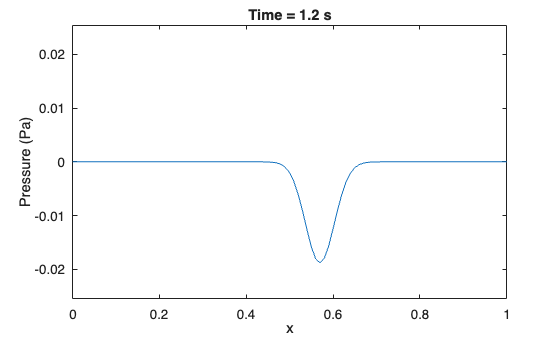

P.animate;